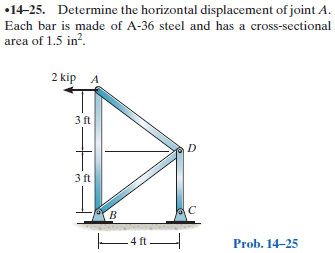

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-25P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-25P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = atand(sym(3/4))*u.deg;
jointA = [0 0]*u.ft;
jointB = [0 -6]*u.ft;
jointC = [4 -6]*u.ft;
jointD = [4 -3]*u.ft;

# member data

E = 29e3*u.ksi;
A = 1.5*u.in^2;

# truss

t = Truss;
t = t.add('reaction', 'Rb', {'Rbx' 'Rby'}, jointB);
t = t.add('reaction', 'Rc', {'Rcx' 'Rcy'}, jointC);
t = t.add('concentrated', 'Pa', [-2 0]*u.kip, jointA);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fad', jointA, jointD, E, A);
t = t.add('member', 'Fbd', jointB, jointD, E, A);
t = t.add('member', 'Fcd', jointC, jointD, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua, 4) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & -0.01421\,\mathrm{in}\\ \mathrm{vA} & -0.002483\,\mathrm{in}\\ \mathrm{uB} & 0\\ \mathrm{vB} & 0\\ \mathrm{uC} & 0\\ \mathrm{vC} & 0\\ \mathrm{uD} & -0.006172\,\mathrm{in}\\ \mathrm{vD} & 0.002483\,\mathrm{in} \end{array}\right)$$

# forces on the truss

ma_f_m_vpa = vpa(ma.f.m) %#ok<NASGU> 

$$ma\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & -1.5\,\mathrm{kip}\\ \mathrm{Fad} & 2.5\,\mathrm{kip}\\ \mathrm{Fbd} & -2.5\,\mathrm{kip}\\ \mathrm{Fcd} & 3.0\,\mathrm{kip} \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Rb} & 2\,\mathrm{kip} & 3\,\mathrm{kip} & 0\\ \mathrm{Rc} & 0 & -3\,\mathrm{kip} & 0\\ \mathrm{Pa} & -2\,\mathrm{kip} & 0 & 0 \end{array}\right)$$

ma_f_c_vpa = vpa(ma.f.c) %#ok<NASGU> 

$$ma\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 1.5\,\mathrm{kip} & 0\\ \mathrm{Fad} & 2.0\,\mathrm{kip} & -1.5\,\mathrm{kip} & 0\\ \mathrm{Fbd} & -2.0\,\mathrm{kip} & -1.5\,\mathrm{kip} & 0\\ \mathrm{Fcd} & 0 & 3.0\,\mathrm{kip} & 0 \end{array}\right)$$

la_f_m_vpa = vpa(la.f.m, 3) %#ok<NASGU> 

$$la\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Rb} & 3.61\,\mathrm{kip}\\ \mathrm{Rc} & 3.0\,\mathrm{kip}\\ \mathrm{Pa} & 2.0\,\mathrm{kip} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fad} & 0\\ \mathrm{Fbd} & 12\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fcd} & 12\,\mathrm{ft}\,\mathrm{kip} \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Rb} & 0 & 0 & 12\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Rc} & 0 & 0 & -12\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pa} & 0 & 0 & 0 \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fad} & 0 & 0 & 0\\ \mathrm{Fbd} & 0 & 0 & -12\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fcd} & 0 & 0 & 12\,\mathrm{ft}\,\mathrm{kip} \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Rb} & 12\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Rc} & 12\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pa} & 0 \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m_vpa ma_f_c_vpa la_f_c la_f_m_vpa;
clear ma_m_m la_m_c ma_m_c la_m_m;